## Interictal signal generated by neural mass model 

% Directed transfer function simulation with stochastic signals
clc,clear,close all
addpath(genpath('MVAR'))
addpath(genpath('Data/NMM/'))

mode = ["Interictal", "Ictal"];
selectMode = mode(2)

selectMode = "Ictal"

signal = load(sprintf("Patient_2/%s_1.mat", selectMode))

signal = struct with fields:
    seg: [-0.6926 -0.4381 0.3359 0.4791 0.1940 0.3247 -0.0184 -0.6834 -0.0953 -0.2896 -0.9717 -0.9245 -0.7927 -0.9121 -0.9751 -0.7328 -0.0970 -0.5477 -0.3483 0.2018 0.3394 0.1660 -0.5415 -0.6633 -0.9398 -0.7666 -0.8982 -0.3740 0.3958 … ] (1×15360 double)


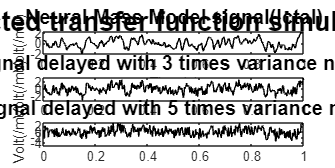


% Interictal signal 
rngSig1 = signal.seg;
rngSig1 = rngSig1(1:400);

signalLength = linspace(1,length(rngSig1),length(rngSig1));
sig1Std = std(rngSig1);

% Signal 2 and signal 3 generated 
rngSig2 = rngSig1 + sqrt(9)*sig1Std*rand(length(rngSig1), 1)';    % One step delayed with 9 times variance added
rngSig3 = rngSig1 + sqrt(25)*sig1Std*rand(length(rngSig1), 1)';    % Two step delayed with 9 times variance added 

% Standard deviation calculated
stdSig1 = std(rngSig1);
stdSig2 = std(rngSig2);
stdSig3 = std(rngSig3);

% Variation calculated
varSig1 = stdSig1^2;
varSig2 = stdSig2^2;
varSig3 = stdSig3^2;

% Demean 
rngSig1 = rngSig1 - mean(rngSig1);
rngSig2 = rngSig2 - mean(rngSig2);
rngSig3 = rngSig3 - mean(rngSig3);

%
x = linspace(0, 1, length(signalLength)-2);
figure
subplot(3,1,1)
plot(x, rngSig1(3:end),"k")
xlabel("Time(s)")
ylabel("Volt(/mu)")
title(sprintf("Neural Mass Model signal(%s)", selectMode),'FontSize',12)

subplot(3,1,2)
plot(x, rngSig2(2:end-1),"k")
xlabel("Time(s)")
ylabel("Volt(/mu)")
title("1-step signal delayed with 3 times variance noise added",'FontSize',12)

subplot(3,1,3)
plot(x, rngSig3(1:end-2),"k")
xlabel("Time(s)")
ylabel("Volt(/mu)")
title("2-steps signal delayed with 5 times variance noise added",'FontSize',12)

sgtitle("Directed transfer function simulation", 'fontsize', 16, 'FontWeight', 'bold')
set(gcf, 'Position', [100, 100, 800, 400]);

% Directed transfer function calculation 
dat = [rngSig1(3:end); rngSig2(2:end-1); rngSig3(1:end-2)];

% order
max_p = 15;
crit_type = "AIC"

crit_type = "AIC"

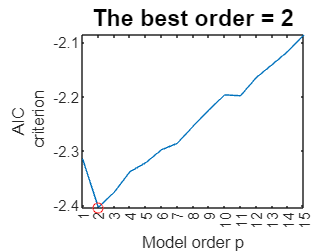

Fs = 400;
do_plot = true; 
[crit, p_range, p_opt] = mvar_criterion(dat, max_p, crit_type, do_plot);
title(['The best order = ', num2str(p_opt)], "FontSize",14)
xlim([1,15])
xticks(1:15)



[Ar, V]=AR_coeff(dat, p_opt);
f = (0:1:200)';
N_f = length(f);
[H, A] = mvar_H(Ar, f, Fs);  %sampling rate: 500

DTF 

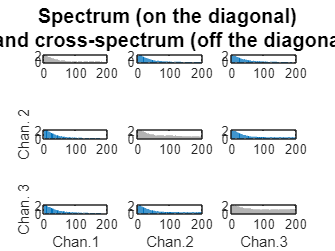

N_chan = 3; 

S = zeros(N_chan,N_chan, N_f);
for fi = 1:length(f)
    S(:,:,fi) = H(:,:,fi)*V*(squeeze(H(:,:,fi))');
end
mvar_plot(S, S, f, 'Chan.', 'Chan. ', {'Spectrum (on the diagonal) ', ' and cross-spectrum (off the diagonal)'},'sqrt');

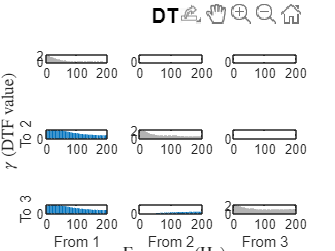


NDTF = abs(H).^2; % normalized

DTF = zeros(N_chan,N_chan, N_f);
for i = 1:N_chan % rows
    for j = 1:N_chan % columns
        DTF(i,j,:) = NDTF(i,j,:)./sum(NDTF(i,:,:),2);
    end
end

mvar_plot(S, DTF,   f, 'From ', 'To ', {'DTF',  ' '},'sqrt');
han = axes(gcf, 'visible', 'off'); % 創建隱藏的軸
han.XLabel.Visible = 'on';
han.YLabel.Visible = 'on';
xlabel(han, "Frequency(Hz)", 'Interpreter', 'latex')
ylabel(han, '$\gamma$ (DTF value)', 'Interpreter', 'latex')
set(gcf, 'Position', [100, 100, 800, 600]);

% **調整標籤位置**
han.XLabel.Position = [0.5, -0.1, 0];  % X 軸標籤往下移
han.YLabel.Position = [-0.1, 0.5, 0];  % Y 軸標籤往左移

## Compute coherence.

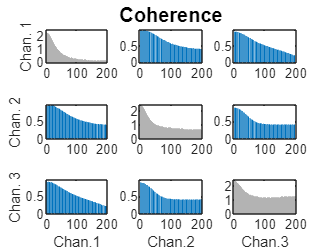

gamma = zeros(N_chan,N_chan, N_f);
for i = 1:N_chan
    for j = 1:N_chan
        gamma(i,j,:) = S(i,j,:)./sqrt(S(i,i,:).*S(j,j,:));
    end
end
mvar_plot(S, gamma, f, 'Chan.', 'Chan. ', {'Coherence'},'sqrt');

## **Error distribution plot**

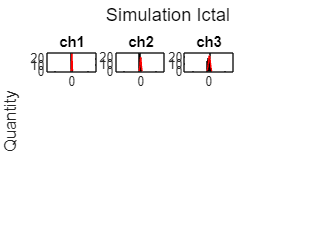

% ------error estimation (畫圖)----
ar_data=zeros(size(dat));
compared_data=double(dat);
titleName = sprintf("Simulation %s", selectMode);
p = p_opt;

for x=(p+1):size(ar_data,2)
    tmp=zeros([size(ar_data,1),1]);
    for y=1:p
        tmp=tmp+Ar(:,:,y)*compared_data(:,x-y);
    end
    ar_data(:,x)=tmp;
end

time=linspace(0,1,size(compared_data,2));
compared_data=compared_data(:,(p+1):end);
ar_data=ar_data(:,(p+1):end);
time=time(:,(p+1):end);


fit_error=compared_data-ar_data;
fig = figure();
for x=1:3
    subplot(4,4,x);
    h=histfit(fit_error(x,:),30);
    set(h, 'Linewidth',0.5);
    xlim([-30,30])
    title(sprintf("ch%d",x));
end
sgtitle(titleName)
% Give common xlabel, ylabel and title to your figure
han=axes(fig,'visible','off');
han.YLabel.Visible='on';
ylabel(han,"Quantity");
xlabel(han,"Error(\muV)");

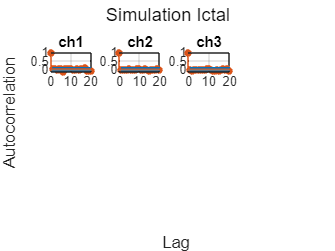


fig = figure();
for x=1:3
    subplot(4,4,x);
    autocorr(fit_error(x,:))
    xlabel("")
    ylabel("")
    title(sprintf("ch%d",x));
end

sgtitle(titleName)
% Give common xlabel, ylabel and title to your figure
han=axes(fig,'visible','off');
han.Title.Visible='on';
han.XLabel.Visible='on';
han.YLabel.Visible='on';
ylabel(han,"Autocorrelation");
xlabel(han,"Lag");